# Dead beat controller design  -  Advanced topic

Control is commonly implemented in discrete time. In order to be able to analyse behaviour in discrete time the user needs some understanding of discrete time models and how these can be handled in MATLAB. Often discrete models can be treated using z-transforms which MATLAB handles formally using tools in the control toolbox. The basic definition and usage of such discrete models is discussed in files ***discrete_models_and_usage.mlx  ***and ***discretization_and_bode.mlx***

The most commonly used PID controller design can be performed also in discrete case. Discrete PID controller design with pole cancellation is discussed in file ***discrete_models_and_discrete_PID_controller_design.mlx***

If the process contains big dead time (e.g. transport delay), with PID control the control system can not be fast, as for ensuring a phase margin of about ${60}^{\circ }$,  the cut-off frequency is restricted to $\omega_c \approx \frac{1}{2\left(T_d +T_s \right)}$, where $T_d$ is the dead time and $T_s$ is the sampling time. (As it was discussed in file  ***discrete_models_and discrete_PID_controller_design.mlx ***sampling and zero order hold introduces extra delay into the control system.)

Referring to PID controller design in the frequency domain, at the cut-off frequency the open loop asymptotic Bode diagram should have a slope of -20dB/decade, and for calm transient behaviour generally a phase margin of about 60 degrees is required. This is reached if the cut-off frequency is set to the value given above. With a big dead time in the process the settling time will be high, its value is approximated by $\frac{3}{\omega_c }\le T_{\textrm{settling}} \le \frac{10}{\omega_c }$.

In the discrete case there are some controller design methods which may result in faster behaviour in the case of big dead times, as compared to the above mentioned design method. This can be an important practical issue. Such controller design methods are dead beat control, Smith predictor controller design,  Youla parameterisation and predictive control. 

This file discusses dead beat controller design.

### Similar files and the toolbox

See website below for more files like this.        [https://controleducation.sites.sheffield.ac.uk/matlabresources/section-6-11-community-control-toolbox](https://controleducation.sites.sheffield.ac.uk/matlabresources/section-6-11-community-control-toolbox) 

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Ruth Bars, Budapest University of Technology and Economics

and J.A. Rossiter, University of Sheffield                                                      

                                          

Reference: Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019.                     

## Table of contents

- Block diagram of the discrete control system

- Dead beat control algorithm

- When do intersampling oscillations occur?

- Dead beat control algorithm avoiding intersampling ripples

## 1.Block diagram of the discrete control system

The block diagram of the discrete control system is given in Figure 1 below. The plant is continuous characterised by its contrinuous time transfer function *G(s)*. Its output is sampled with sampling time $T_s$, and in its input a zero order hold is applied. The parts within the dotted box, including the digital/analog converter at the input and the analog/digital converter at the output of the plant, are described by the pulse transfer function $G\left(z\right)$. The controller is given by pulse transfer function *M(z)* and works in discrete time. 

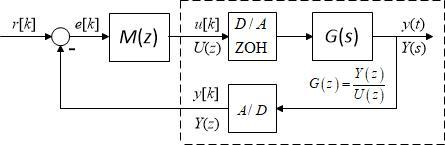

**Figure 1**: *Block diagram representation of a discrete control feedback loop*

The model *G(s)* of the plant is given in continuous time form, desribed by its transfer function. Sampling and holding introduces extra delay into the system, its value is typically between the half and the entire sampling time . The controller *M(z)* is discrete, its output values are calculated at the sampling instants and the zero order hold ZOH provides the continuous input at the input of the process. 

For this resource it is assumed that the plant itself is stable. A step reference signal *r[k]* is used and the discussion below is restricted to this case (albeit the method can be extended to other typical reference signals as well.)

## 2. Dead beat control algorithm

Deadbeat control is a useful concept in control, albeit one would not normally implement such a controller as it is likely to lack robustness. Nevertheless, it defines limits on performance and can provide useful insight.

In simple terms, a deadbeat controller is one which drives the output to a constant value (ideally the reference), within precisely *d* samples; the most aggressive of this will set *d* equal to the model order.  One could go further and ask that the output follows the reference step precisely after the system delay, although this requires the cancelling of system zeros which would not be possible should any of these lie outside the unit circle.

For discrete systems it can be prescribed that the output should reach the step reference value within d sampling steps, where the smallest possible value with be $d=\textrm{round}\left(\frac{T_d }{T_s }\right)+1$ (using rounding up to the nearest integer).

So the target is to define a discrete controller *M(z*) such that pulse transfer of the closed loop transfer function (target to output) should be 

$T\left(z\right)=\frac{G\left(z\right)M\left(z\right)}{1+G\left(z\right)M\left(z\right)}=z^{-d}$.

Let the pulse transfer function of the plant be:

$G\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}\;z^{-d}$, where *B*(*z*) and *A*(*z*) are the numerator and the denominator polynomials in the *z* variable. hence, the closed loop transfer function is described as:


$$T\left(z\right)=\frac{M\left(z\right)G\left(z\right)}{1+M\left(z\right)G\left(z\right)}=\frac{B\left(z\right)M\left(z\right)}{A\left(z\right)+B\left(z\right)M\left(z\right)}$$


Assuming that T(z) is defined as $T\left(z\right)=z^{-d}$, then the required controller can be calculated as:

$M\left(z\right)=\frac{T\left(z\right)}{G\left(z\right)\left(1-T\left(z\right)\right)}=\frac{A\left(z\right)}{B\left(z\right)\left(1-z^{-d} \right)}$    (1)

This controller contains an integrating term (z-1), therefore the output of the control system for step reference input will have no offset.

**Remark**: The process numerator is in the denominator of  this compensator which means there is an assumed exact cancellation between the compensator and process. Consequently, this design cannot be used if there are any unstable zeros, as any uncertainty would result in unstable signals internal to the loop.

### 2.1 Numerical examples

#### Example 2.1

The code below demonstrates the simplicity of the above design method, that is the control law given in equation (1).

The transfer function of the plant is 

$G\left(s\right)=\frac{e^{-10s} }{1+5s}$; 

The sampling time is $T_s =2\ldotp 5$. The reference signal is a unit step. Design a dead beat controller. Give its pulse transfer function. Simulate the output and the control signal. 

disp('EXAMPLE 2.1')

EXAMPLE 2.1


clear
disp('Design of a dead beat controller')

Design of a dead beat controller


s=zpk('s');
G=1/(1+5*s)       % Continuous Model without the delay

G =
 
    0.2
  -------
  (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties


Ts=2.5;           % sampling time
z=zpk('z',Ts);
disp('The pulse transfer function')

The pulse transfer function


Gz=c2d(G,Ts);   %or alternatively Gz=c2d(G,Ts,'zoh'), discrete model
Gz1=Gz*z^-4     % Discrete model with the delay

Gz1 =
 
     0.39347
  --------------
  z^4 (z-0.6065)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The desired closed-loop transfer function')

The desired closed-loop transfer function


Tz=z^-5

Tz =
 
   1
  ---
  z^5
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The controller')

The controller


Mz=Tz/(Gz1*(1-Tz))

Mz =
 
               2.5415 z^9 (z-0.6065)
  -----------------------------------------------
  z^5 (z-1) (z^2 + 1.618z + 1) (z^2 - 0.618z + 1)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('Closed-loop transfer functions')

Closed-loop transfer functions


Gcuz=feedback(Mz,Gz1)      % Closed-loop transfer function target to input

Gcuz =
 
   2.5415 z^5 (z-0.6065)^2 (z+4.03e-05) (z-4.029e-05) (z^2 - 1.2e-08z + 1.624e-09) (z^2 + 0.0002013z + 2.027e-08) (z^2 - 0.0002013z + 2.027e-08)
  -----------------------------------------------------------------------------------------------------------------------------------------------
  z^5 (z-0.6065) (z+0.02273) (z^2 - 0.04325z + 0.0005304) (z^2 + 0.03502z + 0.0005185) (z^2 - 0.02274z + 0.0005275) (z^2 + 0.008242z + 0.0005229)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.


Gcyz=feedback(Gz1*Mz,1)    % Closed-loop transfer function target to input

Gcyz =
 
                                       z^9 (z-0.6065)
  ----------------------------------------------------------------------------------------
  z^9 (z-0.6065) (z-0.001079) (z^2 + 0.001747z + 1.166e-06) (z^2 - 0.0006677z + 1.165e-06)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


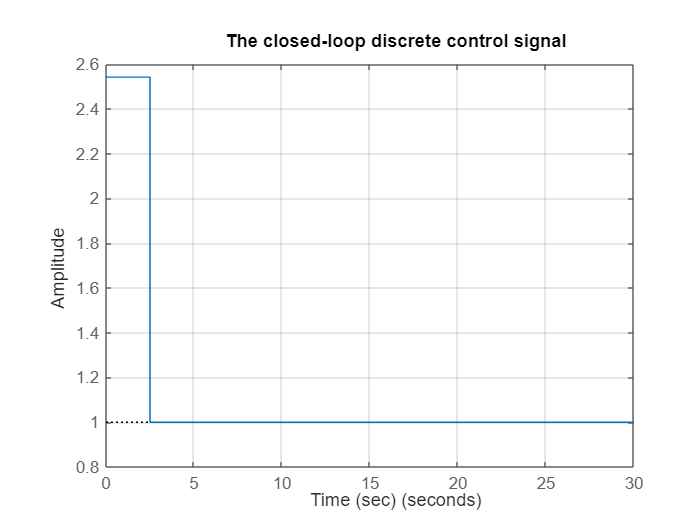



tfinal=30; %=0:2.5:30;
step(Gcuz,tfinal),grid
title('The closed-loop discrete control signal')
xlabel('Time (sec)')

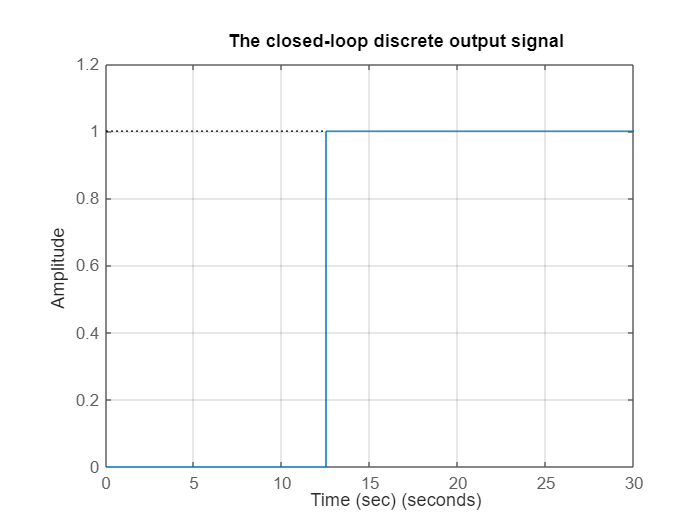

step(Gcyz,tfinal),grid
title('The closed-loop discrete output signal')
xlabel('Time (sec)')

It is seen that the discrete output is settled exactly at 12.5 sec, as desired. The input is somewhat aggressive during transients, but that is to be expected given the demanding specification. Inspection of the closed-loop transfer functions will indicate that, in effect there are some pole/zero cancellations and also poles very close to the origin. These have not been removed because of course, in a real scenario, slight uncertainty would imply these are no longer exact. If you wish to remove them, use the file ***minreal.m***.

The controller is high order and again, that is to be expected given that with the delay the system is in essence 5th order.

#### Example 2.2

This is example is similar to the previous with the main difference being a small increase in the order of the open-loop system.

The transfer function of the plant is

$G\left(s\right)=\frac{e^{-12s} }{\left(1+4s\right)\left(1+10s\right)}$; The sampling time is $T_s =2$. The reference signal is a unit step. Design a dead beat controller. Give its pulse transfer function. Simulate the output and the control signal. 

disp('EXAMPLE 2.2')

EXAMPLE 2.2


clear
disp('Design of a dead beat controller')

Design of a dead beat controller


s=zpk('s');
G=1/((1+4*s)*(1+10*s))

G =
 
       0.025
  ----------------
  (s+0.25) (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


Ts=2;           %sampling time
z=zpk('z',Ts);
disp('The pulse transfer function')

The pulse transfer function


Gz=c2d(G,Ts);   %or alternatively Gz=c2d(G,Ts,'zoh'), discrete model
Gz1=Gz*z^-6

Gz1 =
 
     0.039803 (z+0.7919)
  -------------------------
  z^6 (z-0.8187) (z-0.6065)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The design objective')

The design objective


Tz=z^-7

Tz =
 
   1
  ---
  z^7
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


% The controller
Mz=Tz/(Gz1*(1-Tz))

Mz =
 
                        25.124 z^13 (z-0.8187) (z-0.6065)
  -----------------------------------------------------------------------------
  z^7 (z+0.7919) (z-1) (z^2 + 1.802z + 1) (z^2 - 1.247z + 1) (z^2 + 0.445z + 1)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


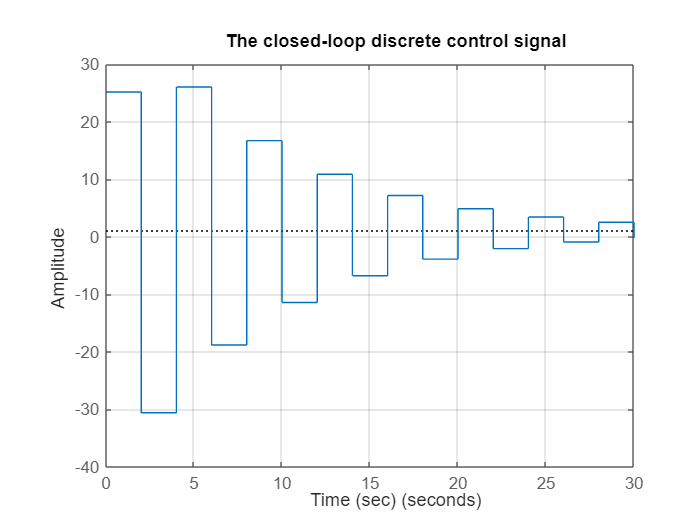

% Closed-loop transfer functions
Gcuz=feedback(Mz,Gz1);      % Closed-loop transfer function target to input
Gcyz=feedback(Gz1*Mz,1);    % Closed-loop transfer function target to input


tfinal=30; %=0:2.5:30;
step(Gcuz,tfinal),grid
title('The closed-loop discrete control signal')
xlabel('Time (sec)')

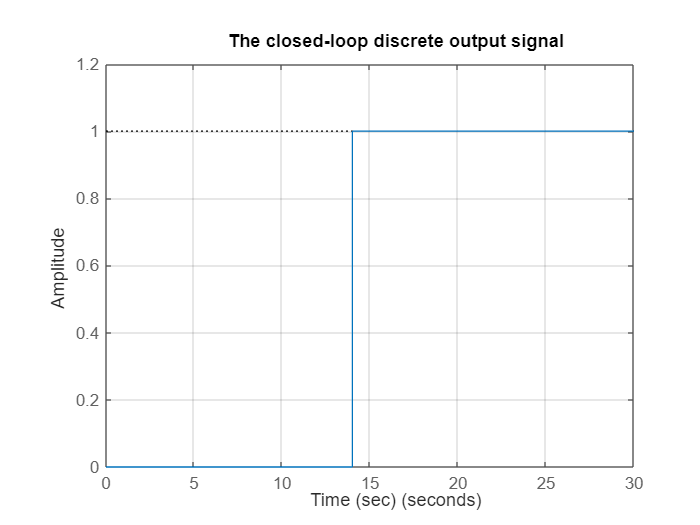

step(Gcyz,tfinal),grid
title('The closed-loop discrete output signal')
xlabel('Time (sec)')

### 2.2 Discussion

The reader may be wondering why within the control signal for example 2.2 there are oscillations, but their effect is not seen in the output signal. However, as will be shown below, this perception is highly misleading and arises because in discrete time, only the output values at the sampling instants are shown. The intersample outputs are not displayed! Indeed, there is a tacit assumption that the outputs move smoothly between their intersample values, but what if this assumption is false?

In order to explore the intersample behaviour it is convenient to run the simulation using simulink and enter the blocks of Figure 1 explicitly. The corresponding simulink disgram is shown in Figure 2. Readers can open and edit this file for their own purposes but the core point is that the intersample behaviour can be exported in the output blocks by setting a suitable time for saving the data. The sample time data can be captured alongside this.

      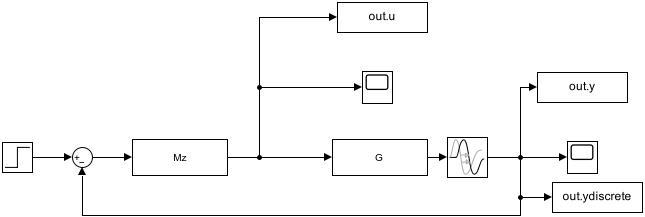

**Figure 2**: Simulink diagram of a discretised control loop, inlcuding the ZOH (***simulink_deadbeat_control101.slx***)

% to open simulink file 
% open simulink_deadbeat_control101.slx

%print(['-ssimulink_deadbeat_control101'],'-djpeg',['simulink_deadbeat_control101.jpg'])

The *Mz* discrete and the *G *continuous transfer function blocks read directly from the workspace. It is not necessary to put a ZOH element between them, as this is embedded within *Mz* automatically within the MATLAB environment, that is, the output of this block is held automatically. Code for running this simulink file is given next. It is important to define in the workspace the variables which the file will be using. This is the same code as from section 2.1. If defined as a variable in the simulink file, the simulation time also needs to be defined.

disp('Data from using the simulink_deadbeat_control101.slx simulink file')

Data from using the simulink_deadbeat_control101.slx simulink file


s=zpk('s');  
G=1/((1+4*s)*(1+10*s));
Ts=2;           %sampling time
z=zpk('z',Ts);
Gz1=c2d(G,Ts)*z^-6;
Tz=z^-7;
Mz=Tz/(Gz1*(1-Tz));

% Simulation
deadtime=12;  % in seconds not samples
endtime=30;
tplot = 0.2;  % Sample rate for collecting data from simulink
Data= sim('simulink_deadbeat_control101.slx');

Model 'simulink_deadbeat_control101' was exported from R2024a to R2023b. To find blocks that were removed during the export operation, click here. Save the model to remove this notification.


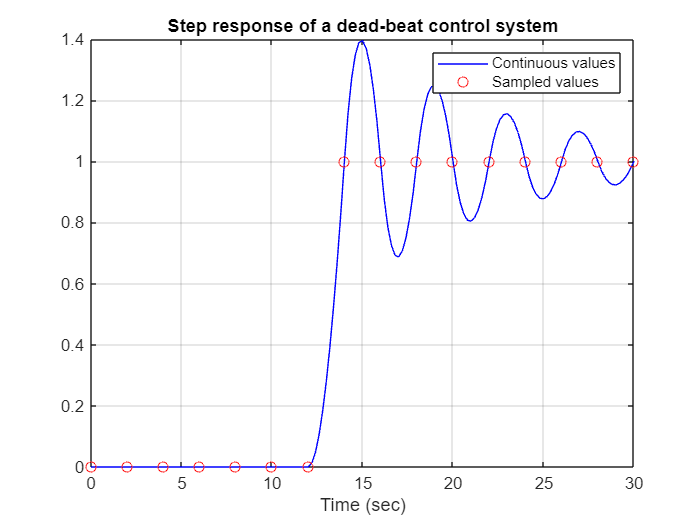

y=Data.y.signals.values;
u=Data.u.signals.values;
t = Data.u.time;
ydiscrete=Data.ydiscrete.signals.values;
tdiscrete = Data.ydiscrete.time;

% Plotting
plot(t,y,'b',tdiscrete,ydiscrete,'ro'),grid
legend('Continuous values','Sampled values')
xlabel('Time (sec)')
title('Step response of a dead-beat control system')

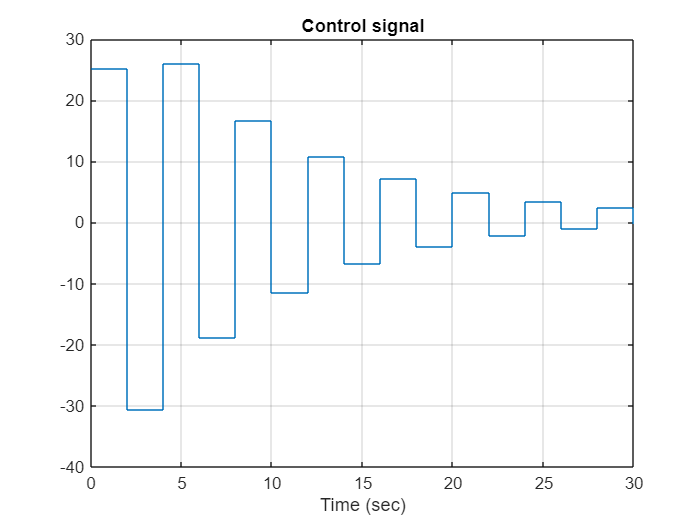

stairs(t,u),grid  % useful function to avoid MATLAB interpolating between different values
title('Control signal')
xlabel('Time (sec)')

It is seen that in the sampling points the output is constant at the reference as desired, but in between there are decreasing oscillations. In other words, the dead-beat controller is misleading if we only look at the values at the sample times.

This is because when calculating the pulse transfer function of the controller *Mz* we cancel the whole dynamics of the pulse transfer function of the plant, and in the denominator of the controller in this case the factor z+0.7919 does appear. If the plant is of higher order, then in the numerator of its pulse transfer function zeros outside the unit circle do appear and the dead beat control will become unstable while in the sampling points the output signal will be exactly 1.

Therefore a modification of the dead beat algorithm is required. 

## 3. When do intersampling oscillations occur?

As it was seen in the denominator of the controller *M(z)* the numerator *B(z)* of the plant does appear, so the controller cancels the zeros of the plant which may not be a good idea in general.

Let us consider lag elements as possible models of the plant.

In the table below the expressions of the transfer functions G(s) and the corresponding pulse transfer functions *G(z)* of the first, second and third order lag elements are given, where $T_1$, $T_2$ and $T_3$ are time constants, $T_s$ is the sampling time, and *k*, $\sigma_1$ and $\sigma_2$ are constants. The pulse transfer functions can be calculated in MATLAB with the ***c2d*** command. 

The zero -$\sigma_1$ of the second order lag element is a real constant inside the unit circle on the left side, one zero of the third order lag element is a real value inside the unit circle on the left side, while the second zero is a real value outside the unit circle on the left side.

The dead beat controller *M(z)* cancels the whole numerator *B(z)* of the plant. 

- Cancelling a zero on the left side inside the unit circle will cause decreasing intersampling oscillations. That is, for example, a pole *z=-0.5* is associated to  oscillatory behaviour. Cancellation of factors of the form $\left(z+a\right)$ imply oscillation will exist between samples.

- Cancelling a zero outside the unit circle (eg. *z=-1.2*) located on the negative real axis will cause increasing intersampling oscillations while in the sampling instants the value of the output will be exactly 1. In this case the control system will become unstable.

A illustration of behaviour associated to different pole positions is shown here where *M1 *has an non-oscillatory pole,* M2 *has an oscillatory pole and *M3* has an oscillatory and divergent pole.

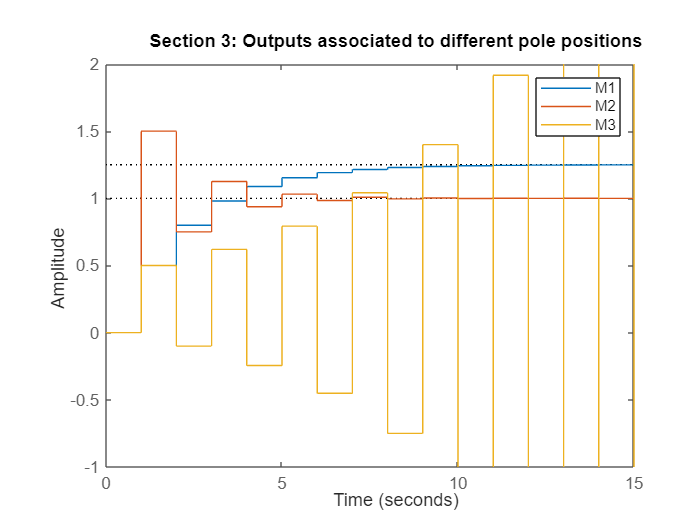


z=zpk('z');
M1=0.5/(z-0.6);
M2=1.5/(z+0.5);
M3=0.5/(z+1.2);
step(M1,M2,M3,15)
legend('M1','M2','M3')
ylim([-1,2])
title('Section 3: Outputs associated to different pole positions')

In summary, we must not cancel any "bad" zeros of the model of the plant or this behavour will reappear in the intersample zones.

## 4. Dead beat control algorithm avoiding intersampling ripples

To avoid intersampling ripples let us separate the numerator to cancellable and non-cancellable factors.

The pulse transfer function of the plant is:


$$G\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}\;z^{-d} =\frac{B_+ \left(z\right)B_- \left(z\right)}{A\left(z\right)}{\;z}^{-d}$$


where $B_+ \left(z\right)$ contains the cancellable factor and  $B_- \left(z\right)$ contains the non-cancellable factor of the numerator of the pulse transfer function. 

Now define the target pulse transfer function of the closed loop as:

$T\left(z\right)={B_{-\;\;} \left(z\right)\;\;z}^{-d}$.

It is important that the gain of $B_- \left(z\right)$ should be 1, so $B_- \left(z\right)|_{z=1} =1$, so the output value for step reference signal would be 1. This change in the target transfer function means that we let the control system settle over a longer time, so we have relaxed the requirements.

The resulting pulse transfer function between the output and the reference signal is now:


$$\frac{M\left(z\right)G\left(z\right)}{1+M\left(z\right)G\left(z\right)}=T\left(z\right)={B_{-\;\;} \left(z\right)\;\;z}^{-d}$$


Hence

$M\left(z\right)=\frac{A\left(z\right)}{B_+ \left(z\right)\left(1-B_- \left(z\right)\;\;z^{-d} \right)}$        (2)

It is advised to give the polynomials with the shift operator $z^{-1}$.

### 4.1. Simulation studies using just MATLAB

This section demonstrates the efficiacy of the design approach for  avoiding intersampling rippling for the system given in example 2.2, that is, it is based on the same example and sample times. The only difference is the use of controller from equation (2) in place of equation (1).

Here we know there is only one zero which is undesirable so the code exploits that knowledge. In general the code would need elaborating to be flexible for different systems.

disp('Section 4.1: Design of a dead beat controller avoiding intersampling ripples')

Section 4.1: Design of a dead beat controller avoiding intersampling ripples



%Continuous and discrete models
s=zpk('s');
G=1/((1+4*s)*(1+10*s));
Ts=2;          %sampling time
z=zpk('z',Ts);
disp('The pulse transfer function')

The pulse transfer function


Gz=c2d(G,Ts);
Gz1=Gz*z^-6;

% define the controller
% Extract the zeros, the poles and the gain of the pulse transfer function
[zer,p,k]=zpkdata(Gz,'v')

zer = -0.7919

p =     0.8187
    0.6065


k = 0.0398

A=(z-p(1))*(z-p(2))/(z*z); % expressed in terms of the shift operator
Bminus=(z-zer)/(z*(1-zer))   % Scaled to give dcgain of unity

Bminus =
 
  0.55805 (z+0.7919)
  ------------------
          z
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


Bplus=k*(1-zer);
disp('The controller')

The controller


Mz=A/(Bplus*(1-Bminus*z^-7))

Mz =
 
                                14.021 z^8 (z-0.8187) (z-0.6065)
  ---------------------------------------------------------------------------------------------
  z^2 (z-1) (z+0.6947) (z^2 + 1.394z + 0.7266) (z^2 - 1.312z + 0.9759) (z^2 + 0.2232z + 0.8971)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties



disp('Closed-loop transfer functions')

Closed-loop transfer functions


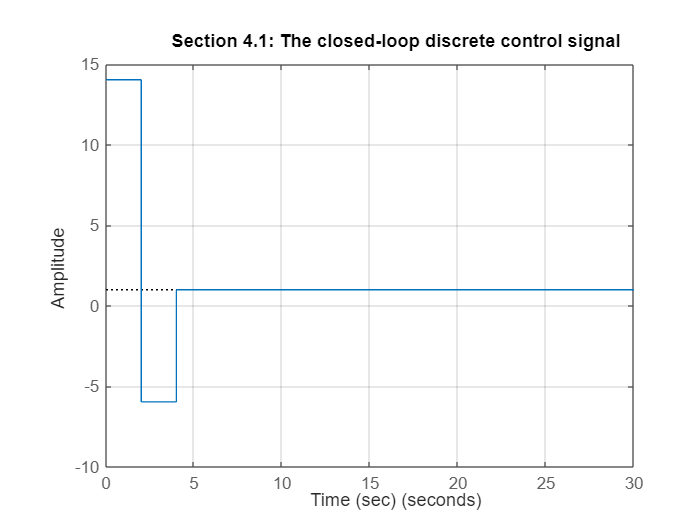

Gcuz=feedback(Mz,Gz1);      % Closed-loop transfer function target to input
Gcyz=feedback(Gz1*Mz,1);    % Closed-loop transfer function target to input

% Simulation and plotting
tfinal=30; %=0:2.5:30;
step(Gcuz,tfinal),grid
title('Section 4.1: The closed-loop discrete control signal')
xlabel('Time (sec)')

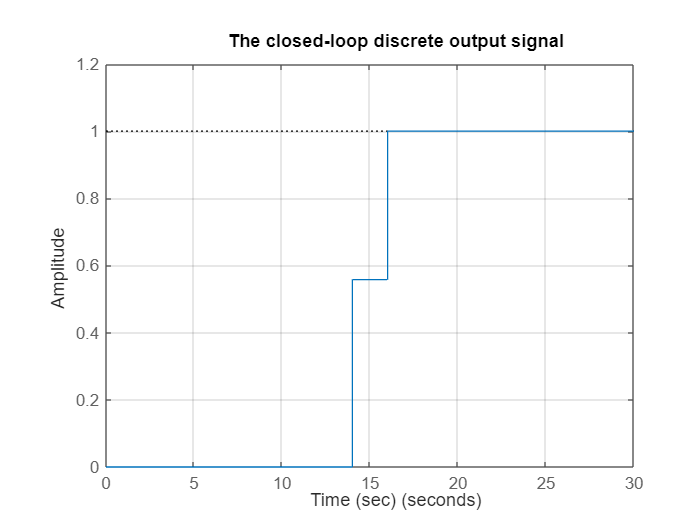

step(Gcyz,tfinal),grid
title('The closed-loop discrete output signal')
xlabel('Time (sec)')

It is seen that the input behaviour is calm, the output is settled within 10 seconds and there are no oscillations in the control signal. However, as expected, the output does not move to the target in a single sample but rather takes 2 samples which is the number of parameters in $B_- \left(z\right)$.

### 4.2 Simulation studies using SIMULINK

To see the intersampling behaviour, we return to the simulink file introduced in section 2.2. The coding is almost exactly the same apart from the definition of *Mz *which is done as in section 4.1 above. Rather than repeating the code from section 4.1, we show here just the simulink aspects and assume the remaining data has already been defined. It is clear that now, unlike in section 2.2, there is no intersample ripple and the output moves to the required steady-state in 2 samples. The control signal is not reproduced as that has not changed.

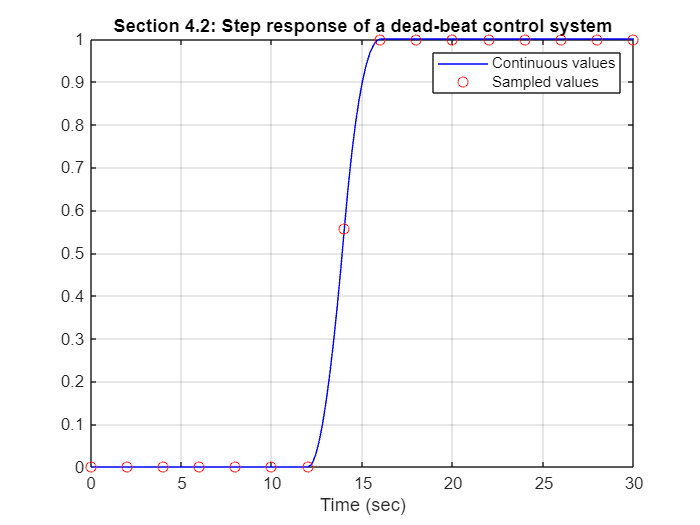

endtime=30;
tplot = 0.2;  % Sample rate for collecting data from simulink
deadtime = 12;  % in seconds not samples
Data= sim('simulink_deadbeat_control101.slx');
y=Data.y.signals.values;
u=Data.u.signals.values;
t = Data.u.time;
ydiscrete=Data.ydiscrete.signals.values;
tdiscrete = Data.ydiscrete.time;

% Plotting
plot(t,y,'b',tdiscrete,ydiscrete,'ro'),grid
legend('Continuous values','Sampled values')
xlabel('Time (sec)')
title('Section 4.2: Step response of a dead-beat control system')

% stairs(t,u),grid  % useful function to avoid MATLAB interpolating between different values
% title('Control signal')
% xlabel('Time (sec)')

### 4.3. Discussion

Readers might like to investigate a wider variety of systems using the code snippets above as templates. However, note that with higher order systems the code for the defintion of *Mz* will need some modification to take account of proper definitions of $B_+ \left(z\right)$ and  $B_- \left(z\right)$ and indeed also a suitable $T\left(z\right)$; parts of the current code are not generic as this makes the code simpler to follow. 

Some aspects worth investigation are:

- What happens if there is uncertainty. For example, deploy a different G(s) in the simulink code to the one used for the compensator design.

- In a similar vein, one could investigate the impact of small errors in the assumed dead-time (this is a parameter in the simulink file).

- The algorithm can be modified further introducing a design polynomial F(z) whose gain is 1,  increasing the settling time with some more steps and decreasing the initial big values of the control signal. Then the closed loop performance will be characterised by $T\left(z\right)={{F\left(z\right)B}_{-\;\;} \left(z\right)\;\;z}^{-d}$.

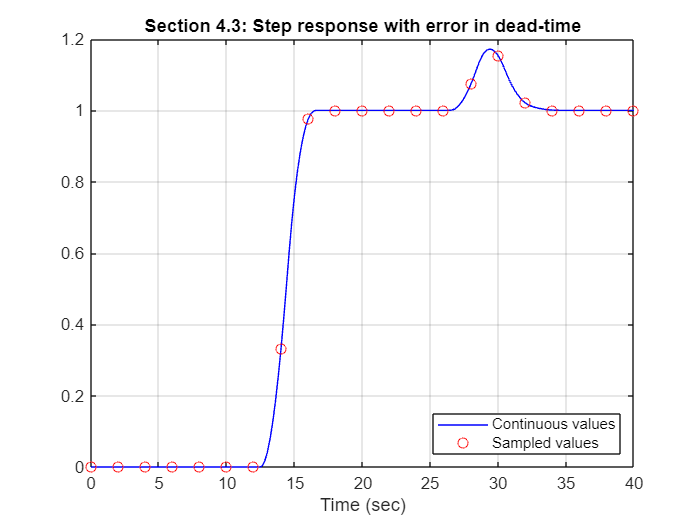

% RUN SECTION 4.2 FIRST TO GENERATE MODEL DATA
deadtime = 12.5;  % in seconds not samples
endtime = 40;
Data= sim('simulink_deadbeat_control101.slx');
y=Data.y.signals.values;
t = Data.u.time;
ydiscrete=Data.ydiscrete.signals.values;
tdiscrete = Data.ydiscrete.time;

% Plotting
plot(t,y,'b',tdiscrete,ydiscrete,'ro'),grid
legend('Continuous values','Sampled values','Location','Southeast')
xlabel('Time (sec)')
title('Section 4.3: Step response with error in dead-time')